# **Identification du système à régler et synthèse du régulateur de courant**

clc;
clear;
close all;
s = tf('s');

## Paramètres

% Données du moteur synchrone
Tn  = 3.3;       % Couple nominal [Nm]
In  = 4.5;       % Courant nominal efficace [A]
U12 = 45;        % Tension efficace à 1000rpm = 1000*2*pi/60 rad/s [V]
R   = 2.7;       % Résistance [Ohm]
L   = 9e-3;      % Inductance [H]
Jm  = 0.24e-3;   % Inertie moteur [kgm^2]

Jt = 4.0230e-04; % Inertie totale
Ke = 0.3509;     % Constante de vitesse
Kt = 0.5185;     % Constante de couple
tau_e = 3.3e-3;  % Constante de temps électrique
tau_m = 6e-3;    % Constante de temps mécanique

% Données du variateur
Kcm = 1;         % Gain [-]
Tr  = 83.3e-6;   % Retard pur [s]

% Données de l'organe de mesure de courant
Kmi = 1;         % Gain [-]
%h2 = 166.7e-6;   % Retard pur [s] ?
tau_mi = 0.001;  % Constante de temps [s] (déterminée manuellement)

% Fonction de transfert
Kai = Jt/(Kt*Ke);
Gai = (Kcm*exp(-s*Tr)) * Kai * (s/(1 + s*tau_m + s*tau_m*tau_e)) * (Kmi/(1 + s*tau_mi));

## 3.

Déterminer la constante de temps dominante équivalente du système à régler (tau dom).

tau_dom = 0;

## 4.

Déterminer la somme des petites constantes de temps

TpE = tau_mi; % ?

## 5.

Ecrire un programme permettant de tracer l'évolution de la bande passante et de l'erreur statique en fonction du facteur N.

## 6.

Pour une marge de phase de 45°, trouver le facteur N qui représente un bon compromis entre erreur statique et bande passante.

Déterminer les paramètres du régulateur PI

% Marge de phase de 45°
mphi     = 45;
w        = logspace(1,4,5000);
Nmin     = 1;
Nmax     = 20;
Ncourbes = 60;

% Calcul des params en fonction de N
[N, wc, Gain, phase, Kpi, Tii, Es] = regul_pi(Gai, Kai, TpE, mphi, w, Nmin, Nmax, Ncourbes);

% Affichage bande passante fct. de N
subplot(2,1,1), plot(N, wc), xlabel('N'), ylabel('wc [rad/s]'), grid, zoom;

% Affichage erreur statique fct. de N
subplot(2,1,2), plot(N, Es*100), xlabel('N'), ylabel('Es [%]'), grid, zoom;

% Meilleurs paramamètres
Kpi_m45 = 0;
Tii_m45 = 0;

fprintf("Marge de phase %f -> Kpi = %f, Tii = %f", mphi, Kpi_m45, Tii_m45);

Marge de phase 45.000000 -> Kpi = 0.000000, Tii = 0.000000

## 7.

Répeter la démarche pour une marge de phase de 60°.

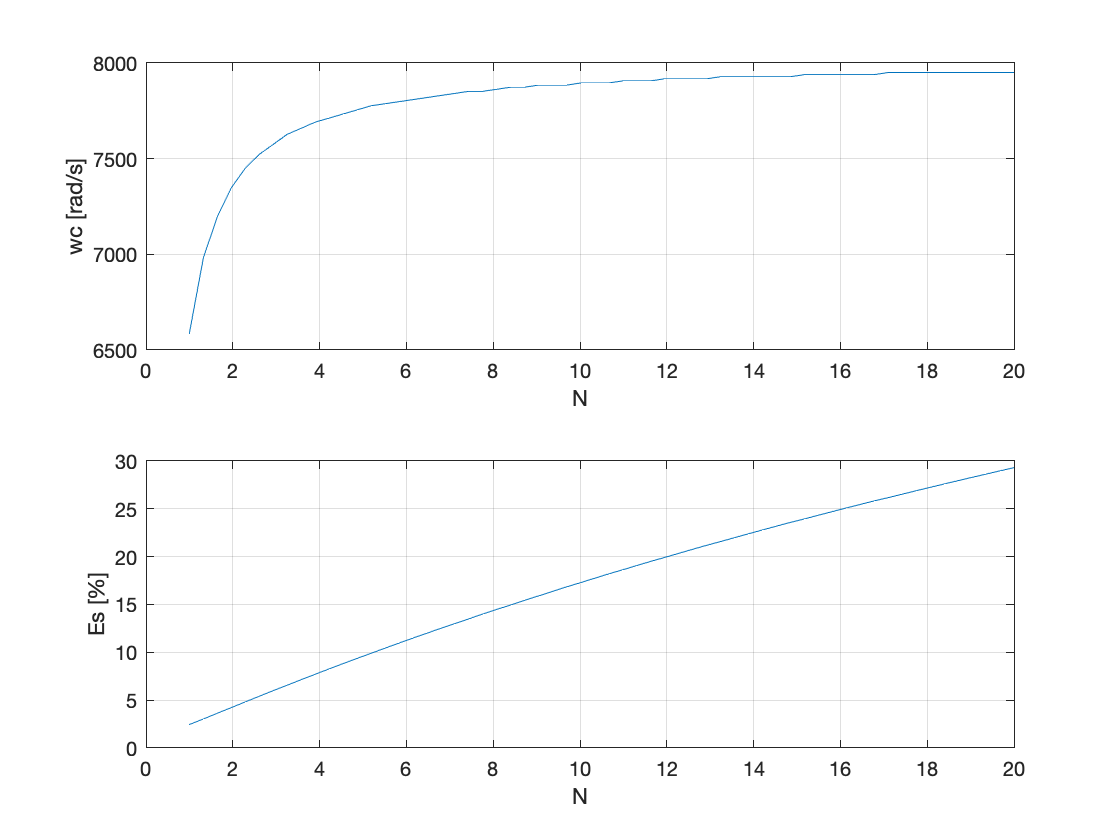

% Marge de phase de 45°
mphi     = 60;
w        = logspace(1,4,5000);
Nmin     = 1;
Nmax     = 20;
Ncourbes = 60;

% Calcul des params en fonction de N
[N, wc, Gain, phase, Kpi, Tii, Es] = regul_pi(Gai, Kai, TpE, mphi, w, Nmin, Nmax, Ncourbes);

% Affichage bande passante fct. de N
subplot(2,1,1), plot(N, wc), xlabel('N'), ylabel('wc [rad/s]'), grid, zoom;

% Affichage erreur statique fct. de N
subplot(2,1,2), plot(N, Es*100), xlabel('N'), ylabel('Es [%]'), grid, zoom;


% Meilleurs paramamètres
Kpi_m60 = 0;
Tii_m60 = 0;

fprintf("Marge de phase %f -> Kpi = %f, Tii = %f", mphi, Kpi_m60, Tii_m60);

Marge de phase 60.000000 -> Kpi = 0.000000, Tii = 0.000000

%plot(N, Kpi), xlabel('N'), ylabel('Kpi [-]'), grid, zoom;
%subplot(2,1,1), semilogx(w, Gain), xlabel('w [rad/s]'), ylabel('Goi [dB]'), ylim([-40 40]);
%subplot(2,1,2), semilogx(w, phase), xlabel('w [rad/s]'), ylabel('phi [°]'), ylim([-180 0]);

%subplot(2,1,1), plot(N, wc), xlabel('N'), ylabel('wc [rad/s]'), grid, zoom;
%subplot(2,1,2), plot(N, Es*100), xlabel('N'), ylabel('Es [%]'), grid, zoom;

## 8.

Commenter les résultats obtenus pour ces deux régulateurs PI (45° et 60° de marge de phase).